**Defining System**

M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

Q=[1000 0 0 0 0 0;
0 0.00001 0 0 0 0;
0 0 1000 0 0 0;
0 0 0 0 0 0;
0 0 0 0 1000 0;
0 0 0 0 0 0];

R=0.0001;


C1=[1 0 0 0 0 0 ];




**Linearized System**

% Vd=0.3*rand( 1 )*eye ( 6 ) ; %Process
% Vn=0.1*rand ( 1 ); %Measurement 
% K=lqr(A,B,Q,R);
% L=lqr(A',C1',Vd,Vn)';
% 
% AL1=[(A-(B*K)) B*K;
%     zeros(size(A)) A-L*C1];
% BL1 = [B ; zeros(size(B))];
% 
% CL1=[C1 zeros(size(C1))];
% 
% DL1=0;
% SS1= ss(AL1,BL1,CL1,DL1);
% 
% figure 
% step(SS1)
% 
% initial_state =  [3,0.3,deg2rad(20),1,deg2rad(-10),2,0,0,0,0,0,0];
% figure 
% initial(SS1,initial_state)

**Plotting Response of Non Linear System **

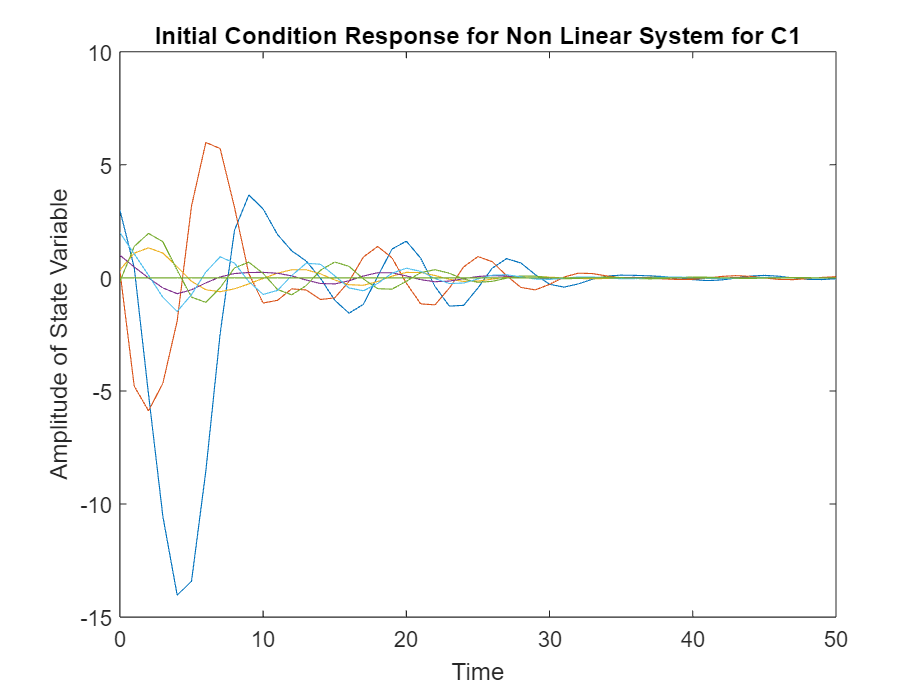

time_span = 0:1:50;
[time,out] = ode45(@(time,input)non_linear(time,input,C1),time_span,initial_state);
figure

plot(time,out)

title('Initial Condition Response for Non Linear System for C1')
xlabel('Time')
ylabel('Amplitude of State Variable')

function value = non_linear(time,input,C)
M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

Q=[10 0 0 0 0 0;
0 0.00001 0 0 0 0;
0 0 1000 0 0 0;
0 0 0 0 0 0;
0 0 0 0 1000 0;
0 0 0 0 0 0];

R=0.0001;


th1 = input(3);
th2 = input(5);

th_dot1 = input(4);
th_dot2 = input(6);
K= lqr(A,B,Q,R);

F=-K*input(1:6);

x_ddot =((F-(m1*sin(th1))*g*cos(th1)+l1*(th_dot1.^2))-(m2*sin(th1)*(g*cos(th2)+l2*(th_dot2^2))))/((M+(m1*(sin(th1).^2)))+m2*(sin(th2).^2));
th_ddot1 = (x_ddot*cos(th1)-g*sin(th1))/l1;
th_ddot2 = (x_ddot*cos(th2)-g*sin(th2))/l2;


Vd=0.3*rand( 1 )*eye ( 6 ) ; %Process
Vn=0.1*rand ( 1 ); %Measurement 

L=lqr(A',C',Vd,Vn)';

estimator = (A-L*C)*input(7:12);

value = zeros(12,1);
value(1) = input(2); 
value(2) = x_ddot;
value(3) = input(4);
value(4) = th_ddot1;
value(5) = input(6);
value(6) = th_ddot2;
value(7) = estimator(1);
value(8) = estimator(2);
value(9) = estimator(3);
value(10) = estimator(4);
value(11) = estimator(5);
value(12) = estimator(6);
end